%Reading the dataset
location = fullfile(pwd, 'Data2');
%location = fullfile(pwd, 'Data2');
ads = audioDatastore(location,'IncludeSubFolders',true,...
    'LabelSource','foldernames');
countEachLabel(ads)

ans = 10×2 table
      Label      Count
    _________    _____

    blues         100 
    classical     100 
    country       100 
    disco         100 
    hiphop        100 
    jazz          100 
    metal         100 
    pop           100 
    reggae        100 
    rock          100 


i = 1;
label = 1;
genre = strings;

%Extracting the data
while hasdata(ads)
    [audioIn, info] = read(ads);
    fs = info.SampleRate;
    genre(i) = append(info.FileName(78),info.FileName(79));
    mfcc_features = mfcc(audioIn, fs);
    
    data(i,:)= [mean(mfcc_features) reshape(cov(mfcc_features).',1,[]) label];
    if(mod(i,100)==0)
        label = label +1;
    end
    i = i+1;
end
len = i-1

len = 1000

% Clear Nan
for i=len:-1:1
    if(sum(isnan(data(i,:)))>0)
        data(i,:)=[];
    end
    
end
size(data)

ans =    989   211


% Normalize data
X = data(:,1:end-1);
X_norm = (X-min(X))./(max(X)-min(X));
X_norm = [X_norm data(:,end)];

### K-Means

%K-means
aux = 0;
aux2= 0;
for i = 1:1000
    [idx,C] = kmeans(X_norm(:,1:end-1),3,'Distance','sqeuclidean');
    %[idx,C] = kmeans(X_norm(:,1:end-1),10,'Distance','sqeuclidean');
    [Acc,rand_index,match]=AccMeasure(data(:,end),idx);
    aux = max(Acc,aux);
    aux3(i)=Acc;
    aux4(i)=rand_index;
    aux2=max(rand_index,aux2);
end
fprintf("Average Accuracy: %i",mean(aux3))
fprintf("Best Accuracy: %i",aux) 
fprintf("Average Rand Index: %i",mean(aux4))
fprintf("Best Rand Index: %i",aux2)

### TSNE

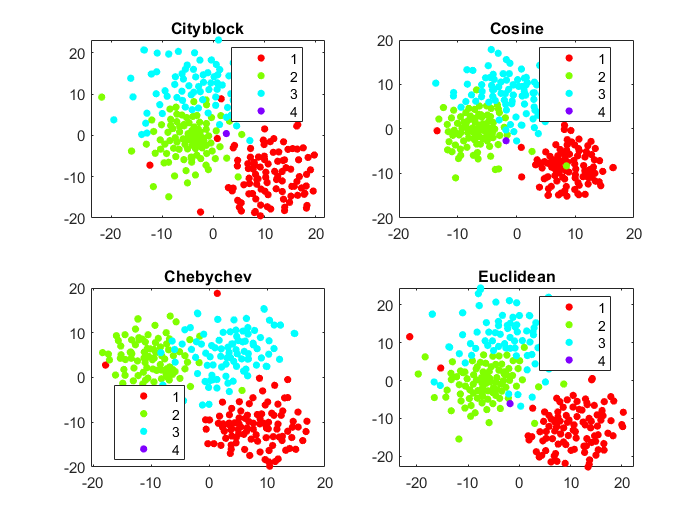

% Tsne 
Y = tsne(X_norm(:,1:end-1));
gscatter(Y(:,1),Y(:,2),X_norm(:,end))

rng('default') % for reproducibility
Y = tsne(X_norm(:,1:end-1),'Algorithm','exact','Distance','cityblock');
subplot(2,2,1)
gscatter(Y(:,1),Y(:,2),X_norm(:,end))
title('Cityblock')

rng('default') % for fair comparison
Y = tsne(X_norm(:,1:end-1),'Algorithm','exact','Distance','cosine');
subplot(2,2,2)
gscatter(Y(:,1),Y(:,2),X_norm(:,end))
title('Cosine')

rng('default') % for fair comparison
Y = tsne(X_norm(:,1:end-1),'Algorithm','exact','Distance','chebychev');
subplot(2,2,3)
gscatter(Y(:,1),Y(:,2),X_norm(:,end))
title('Chebychev')

rng('default') % for fair comparison
Y = tsne(X_norm(:,1:end-1),'Algorithm','exact','Distance','euclidean');
subplot(2,2,4)
gscatter(Y(:,1),Y(:,2),X_norm(:,end))
title('Euclidean')

TSNE 3D 

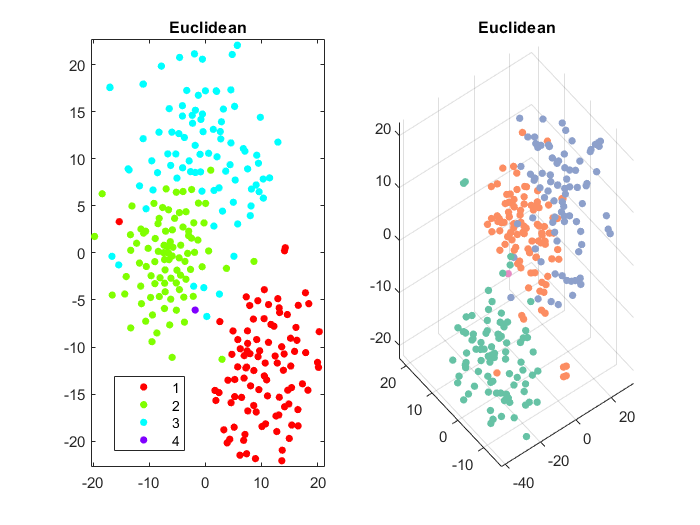

rng('default') % for reproducibility
Y = tsne(X_norm(:,1:end-1),'Algorithm','exact','Distance','cityblock');
subplot(1,2,1);

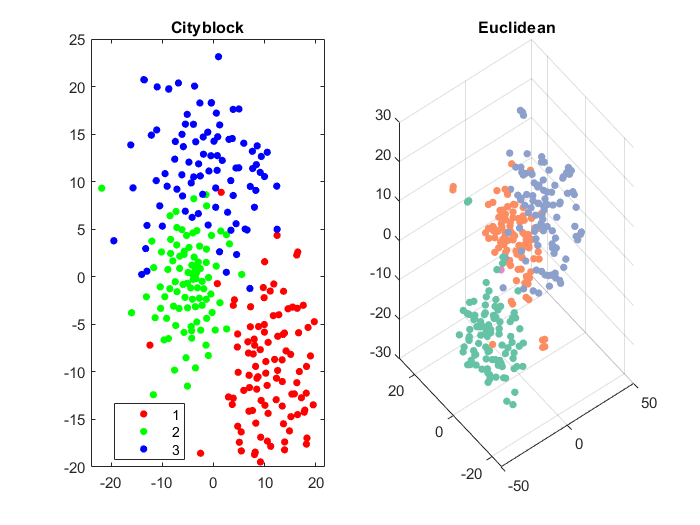

gscatter(Y(:,1),Y(:,2),X_norm(:,end))
title('Cityblock')

group = X_norm(:,end);
colors = brewermap(max(group),'Set2');  %or any other way of creating the colormap
markersize = 20;   %change to suit taste

[Y2,loss2] = tsne(X_norm(:,1:end-1),'Algorithm','exact','Distance','cityblock','NumDimensions',3);
subplot(1,2,2);

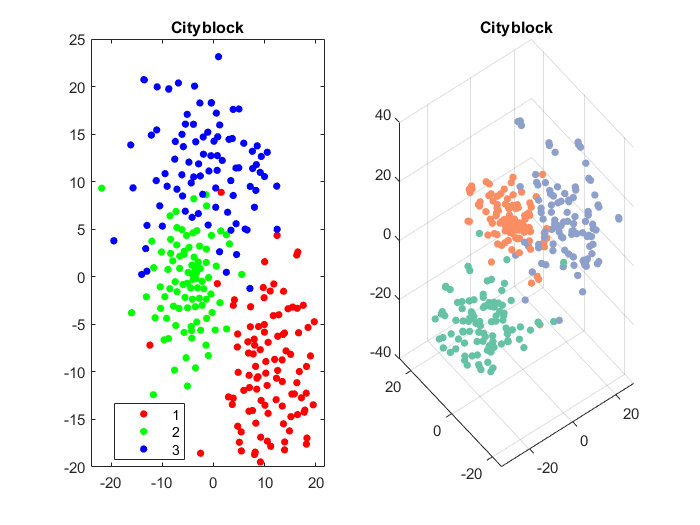

scatter3(Y2(:,1),Y2(:,2),Y2(:,3), markersize, colors(group,:),'filled')
title('Cityblock')

 rng('default') % for reproducibility
Y = tsne(X_norm(:,1:end-1),'Algorithm','exact','Distance','cosine');
subplot(1,2,1);

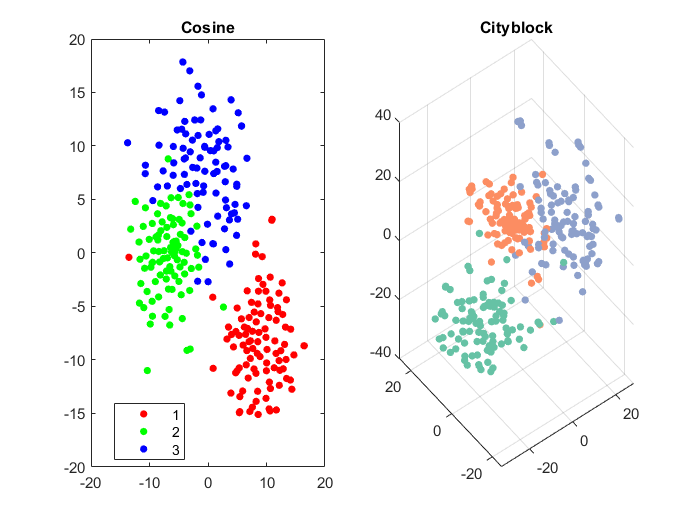

gscatter(Y(:,1),Y(:,2),X_norm(:,end))
title('Cosine')

group = X_norm(:,end);
colors = brewermap(max(group),'Set2');  %or any other way of creating the colormap
markersize = 20;   %change to suit taste

[Y2,loss2] = tsne(X_norm(:,1:end-1),'Algorithm','exact','Distance','cosine','NumDimensions',3);
subplot(1,2,2);

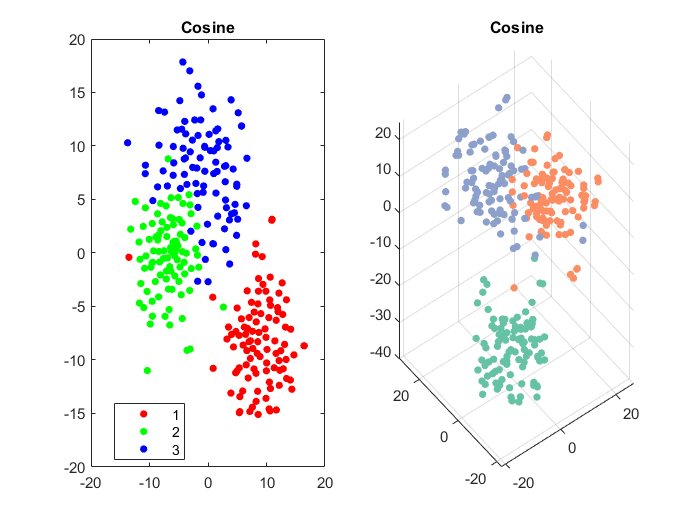

scatter3(Y2(:,1),Y2(:,2),Y2(:,3), markersize, colors(group,:),'filled')
title('Cosine')

rng('default') % for reproducibility
Y = tsne(X_norm(:,1:end-1),'Algorithm','exact','Distance','euclidean');
subplot(1,2,1);

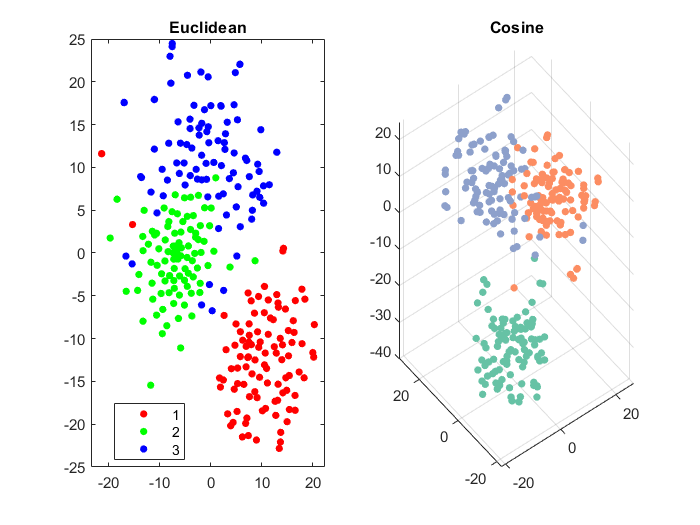

gscatter(Y(:,1),Y(:,2),X_norm(:,end))
title('Euclidean')

group = X_norm(:,end);
colors = brewermap(max(group),'Set2');  %or any other way of creating the colormap
markersize = 20;   %change to suit taste

[Y2,loss2] = tsne(X_norm(:,1:end-1),'Algorithm','exact','Distance','euclidean','NumDimensions',3);
subplot(1,2,2);

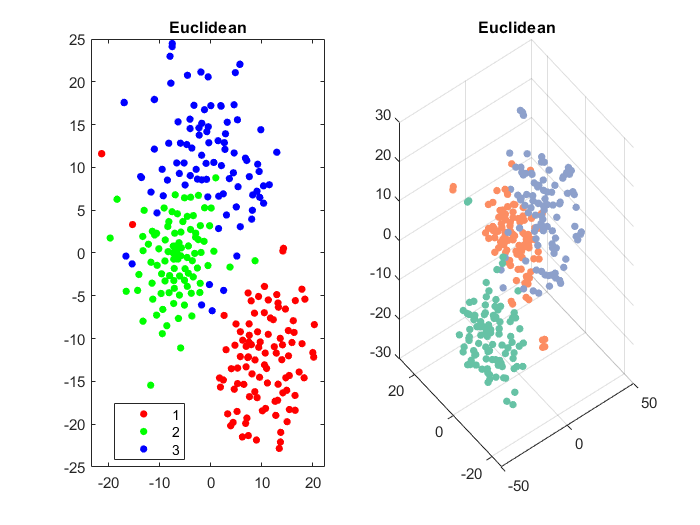

scatter3(Y2(:,1),Y2(:,2),Y2(:,3), markersize, colors(group,:),'filled')
title('Euclidean')

### Substractive Clustering

ras = [0.5 0.7 0.9 1];% parameters of substractive clustering
for i = 4:-1:1
    ra = ras(i);
    centers = substractive(X_norm(:,1:end), ra);
    [m,n]=size(centers);
    fprintf("Hay %i clusters    ",m)
end

After running substractive with K means using the number of clusters suggested by the euclidean metric.

- 10 genres K=8 y K=9

- Classical, Reggae and Metall k=7

- Rock blues and country K=2

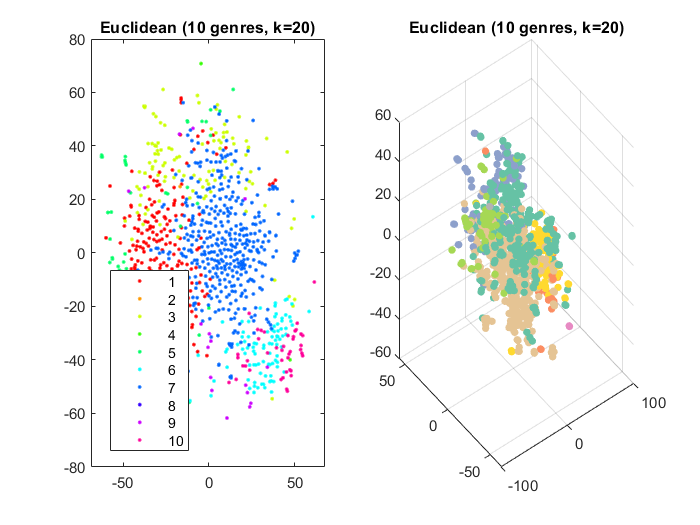

idx = kmeans(X_norm(:,1:end-1),10);

rng('default') % for reproducibility
Y = tsne(X_norm(:,1:end-1),'Algorithm','exact','Distance','cosine');
subplot(1,2,1);

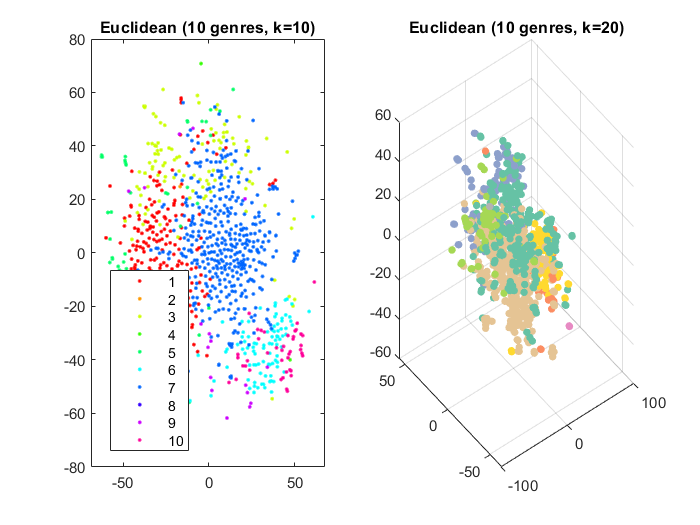

gscatter(Y(:,1),Y(:,2),idx)
title('Cosine (10 genres, k=10)')

group = idx;
colors = brewermap(max(group),'Set2');  %or any other way of creating the colormap
markersize = 20;   %change to suit taste

[Y2,loss2] = tsne(X_norm(:,1:end-1),'Algorithm','exact','Distance','cosine','NumDimensions',3);
subplot(1,2,2);

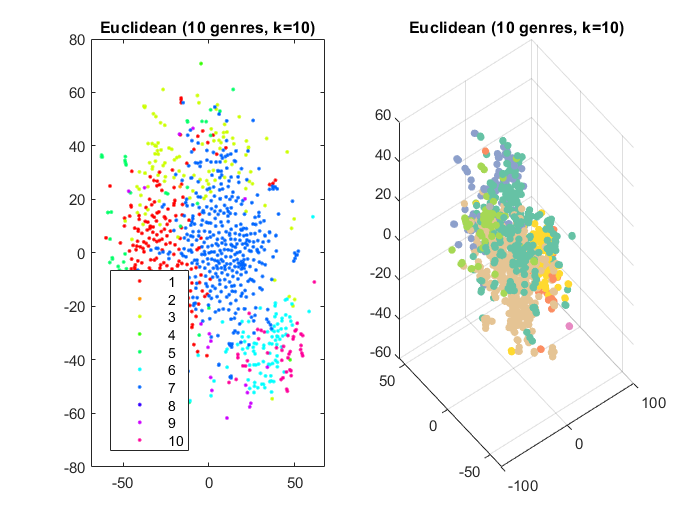

scatter3(Y2(:,1),Y2(:,2),Y2(:,3), markersize, colors(group,:),'filled')
title('Cosine (10 genres, k=10)')